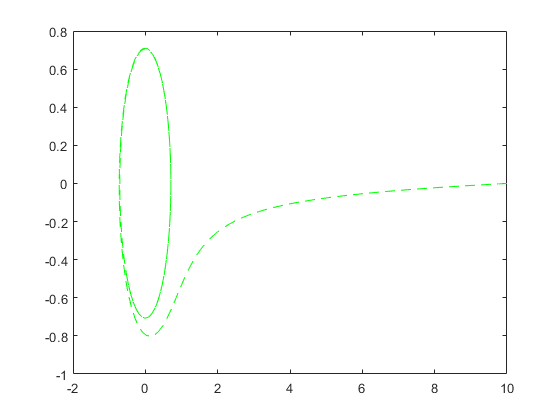

fun = @(t,y) [y(2) + y(1)*(0.5 - y(1).^2 - y(2).^2); -y(1) + y(2)*(0.5 - y(1).^2 - y(2).^2)];

tspan = [0, 15];
y0 = [10, 0];
[t, y] = ode45(fun, tspan, y0);
plot(y(:,1), y(:,2), '--g', y(1,1), y(1,2), '')